clc
clear all;

# **Exercise Session I - Modeling and Phase Space Analysis**

## **The Harmonic Oscillator**

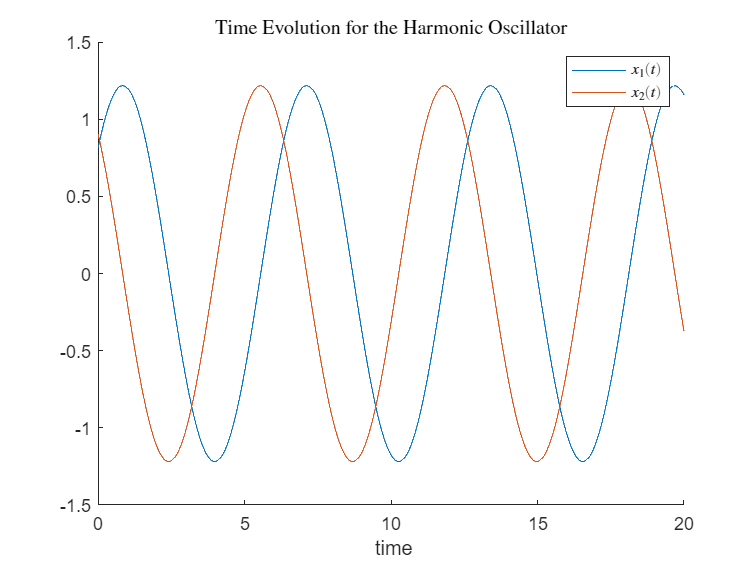

% State Matrix
S = [0 1; -1 0];

% Parametrized Model
dx  = @(t, x) S*x;

% Simulation Variables
T = 20; % Simulation length
dt = 1e-3; % Step size
time_span = 0:dt:T; % simulation horizon

% Plots initialization
figure;
ax = gca;
hold(ax, 'all');

figure;
ax1 = gca;
hold(ax1, 'all');

x0 = rand(1, 2); % random initial condition

[t, x] = ode45(dx, time_span, x0);

title(ax, 'Time Evolution for the Harmonic Oscillator', 'Interpreter', 'latex')
plot(ax, t, x(:, 1), 'DisplayName', '$x_1(t)$');
plot(ax, t, x(:, 2), 'DisplayName', '$x_2(t)$');
legend(ax, 'show', 'Interpreter', 'latex');
xlabel(ax, ' time');

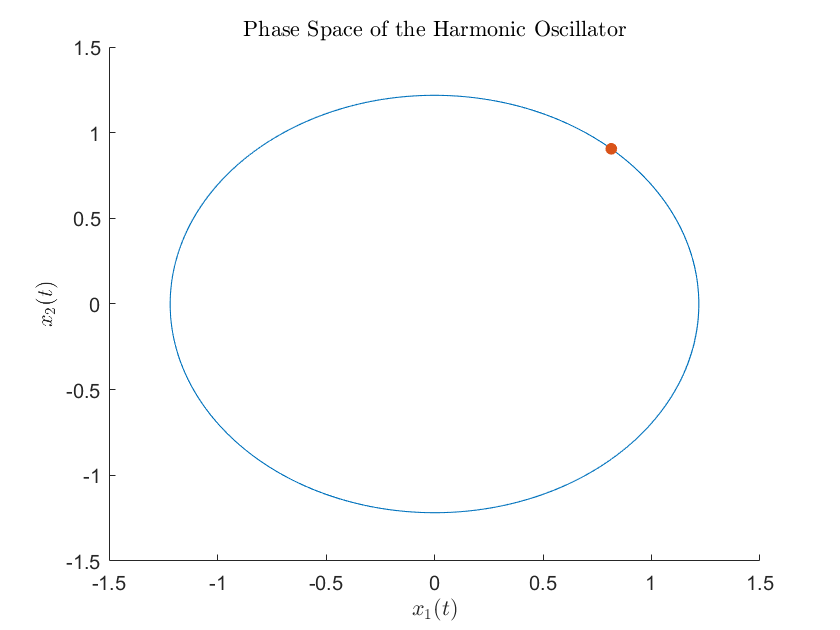


title(ax1, 'Phase Space of the Harmonic Oscillator', 'Interpreter','latex')
plot(ax1, x(:, 1), x(:, 2));
plot(ax1, x0(1), x0(2), 'Marker','.', 'MarkerSize', 20, 'DisplayName', '$x_0$')
xlabel(ax1, '$x_1(t)$', 'Interpreter','latex');
ylabel(ax1, '$x_2(t)$', 'Interpreter','latex');

**Behavior for different initial conditions**

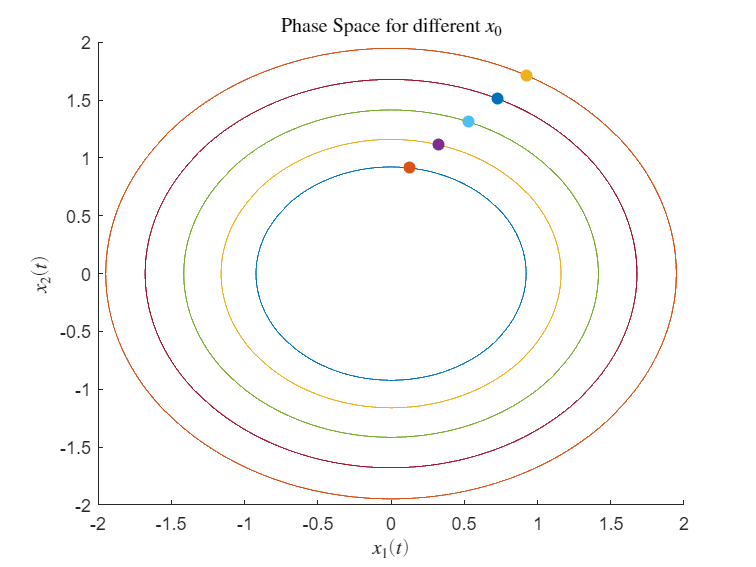

figure;
ax2 = gca;
hold(ax2, 'all');

n_trials = 5;
x0 = rand(1, 2);
delta = 0.2;
for i=1:n_trials
    [t, x] = ode45(dx, time_span, x0);
    title(ax2, 'Phase Space for different $x_0$', 'Interpreter','latex')
    plot(ax2, x(:, 1), x(:, 2));
    plot(ax2, x0(1), x0(2), 'Marker','.', 'MarkerSize', 20)
    xlabel(ax2, '$x_1(t)$', 'Interpreter','latex');
    ylabel(ax2, '$x_2(t)$', 'Interpreter','latex');
    x0 = x0 + delta;
end

What happens if instead of S as introduced above, we have a matrix like:

% where k is a parameters
% S_alpha = [0, alpha; 1, 0]

Try to replicate the previous simulations for varying **alpha**. 

## **Linear Oscillator - parametrized by alpha**

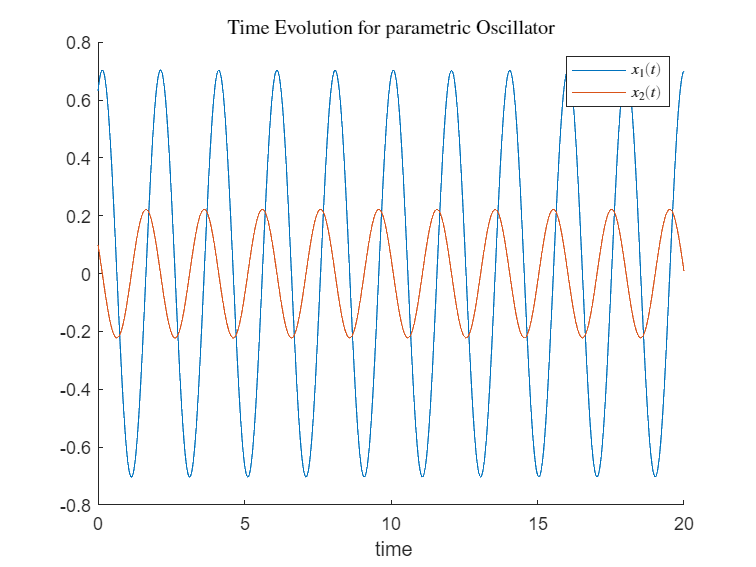

alpha = 10;
S_alpha = [0 alpha; -1 0];

dx_alpha  = @(t, x) S_alpha*x;

T = 20;
dt = 1e-4;

figure;
ax = gca;
hold(ax, 'all');

figure;
ax1 = gca;
hold(ax1, 'all');


time_span = 0:dt:T;
x0 = rand(1, 2);

[t, x] = ode45(dx_alpha, time_span, x0);

title(ax, 'Time Evolution for parametric Oscillator', 'Interpreter', 'latex')
plot(ax, t, x(:, 1), 'DisplayName', '$x_1(t)$');
plot(ax, t, x(:, 2), 'DisplayName', '$x_2(t)$');
legend(ax, 'show', 'Interpreter', 'latex');
xlabel(ax, ' time');

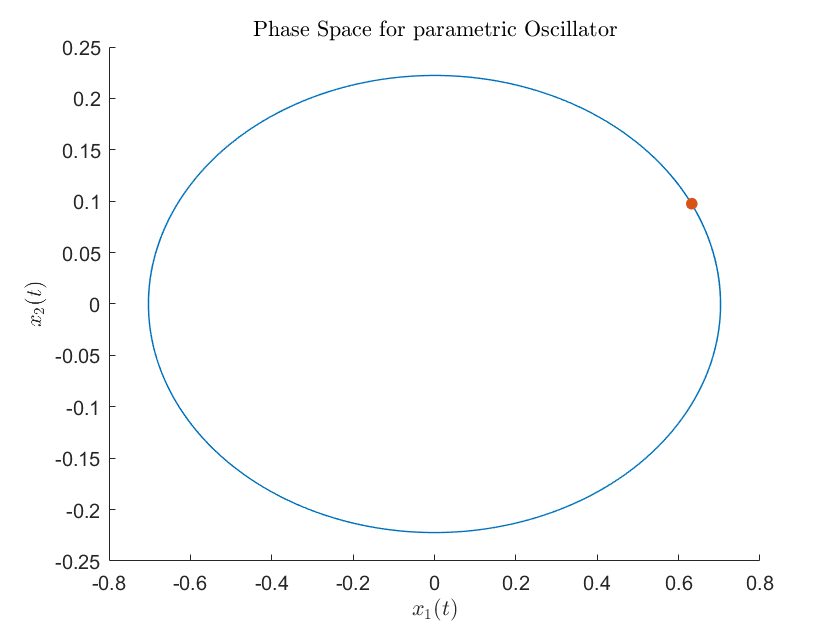


title(ax1, 'Phase Space for parametric Oscillator', 'Interpreter','latex')
plot(ax1, x(:, 1), x(:, 2));
plot(ax1, x0(1), x0(2), 'Marker','.', 'MarkerSize', 20)
xlabel(ax1, '$x_1(t)$', 'Interpreter','latex');
ylabel(ax1, '$x_2(t)$', 'Interpreter','latex');

## Van Der Pol Oscillator

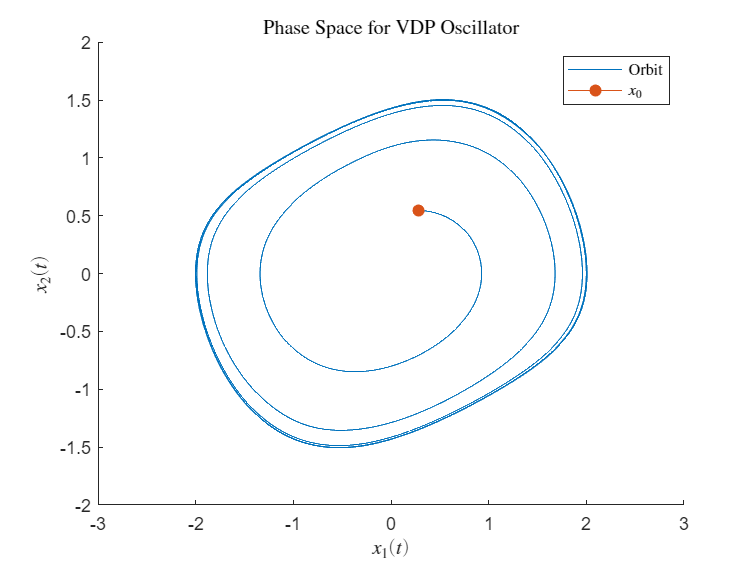

k = 2;
mu = 0.5;
vdp_osc = @(t, x)[
    k * x(2);
    mu*(1 - x(1)^2) * x(2) - x(1)];

T = 200;
dt = 1e-4;
time_span = 0:dt:T;

figure;
ax3 = gca;
hold(ax3, 'all');

x0 = rand(1, 2);
[t, x] = ode45(vdp_osc, time_span, x0);

title(ax3, 'Phase Space for VDP Oscillator', 'Interpreter','latex')
plot(ax3, x(:, 1), x(:, 2), DisplayName='Orbit');
plot(ax3, x0(1), x0(2), 'Marker','.', 'MarkerSize', 20, DisplayName='$x_0$')
legend('Interpreter','latex');
xlabel(ax3, '$x_1(t)$', 'Interpreter','latex');
ylabel(ax3, '$x_2(t)$', 'Interpreter','latex');


% What happens if we start from x0 = 0?

% What happens if we start from x0 = 0 + delta?

% Try to compute and plot the solutions of these two cases. 

## Van der Pol Oscillator - Vector field Plotting

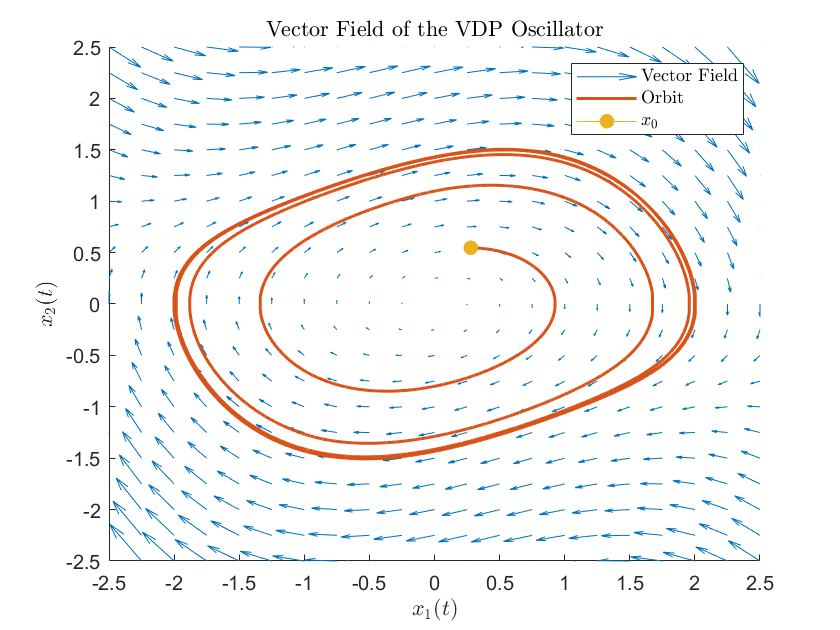

% Define the grid for x1 and x2
[x12_max, x12_min] = deal(2.5, -2.5);
dens = 0.25;
[x1_grid, x2_grid] = meshgrid(x12_min:dens:x12_max, x12_min:dens:x12_max); 

% Initialize u and v components of the vector field
u = zeros(size(x1_grid));
v = zeros(size(x1_grid)); 

% Compute the vector field over the grid
for i = 1:numel(x1_grid)
    vec_field = vdp_osc(0, [x1_grid(i); x2_grid(i)]); % Evaluate the vector field
    u(i) = vec_field(1);  
    v(i) = vec_field(2);  
end

% Plot the vector field using quiver
figure;
ax4 = gca;
hold(ax4, 'all');
quiver(ax4, x1_grid, x2_grid, u, v, 'AutoScale', 'on', 'AutoScaleFactor', 1.5, DisplayName='Vector Field');
plot(ax4, x(:, 1), x(:, 2), 'LineWidth', 1.5, DisplayName='Orbit');
plot(ax4, x0(1), x0(2), 'Marker', '.', 'MarkerSize', 25, DisplayName='$x_0$');
xlabel('$x_1(t)$', 'Interpreter', 'latex');
ylabel('$x_2(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex')
xlim([x12_min, x12_max]);
ylim([x12_min, x12_max]);
title('Vector Field of the VDP Oscillator', 'Interpreter', 'latex');

## Pendulum with Friction

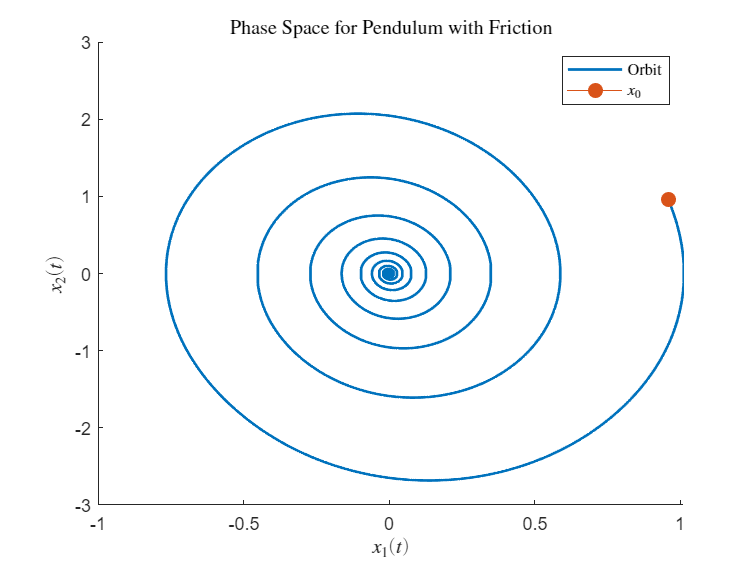

g = 9.81;
l = 1;
m = 1;
c = 0.5;

pendulum = @(t, x) [
    x(2);
    - (g/l)*sin(x(1)) - (c/m*l)*x(2)];

x0 = rand(1, 2);
[t, x] = ode45(pendulum, time_span, x0);

figure;
ax5 = gca;
hold(ax5, 'all');
title(ax5, 'Phase Space for Pendulum with Friction', 'Interpreter', 'latex');
plot(ax5, x(:, 1), x(:, 2), 'LineWidth', 1.5, DisplayName='Orbit');
plot(ax5, x0(1), x0(2), 'Marker', '.', 'MarkerSize', 25, DisplayName='$x_0$');
xlabel('$x_1(t)$', 'Interpreter', 'latex');
ylabel('$x_2(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');

## Pendulum without Friction

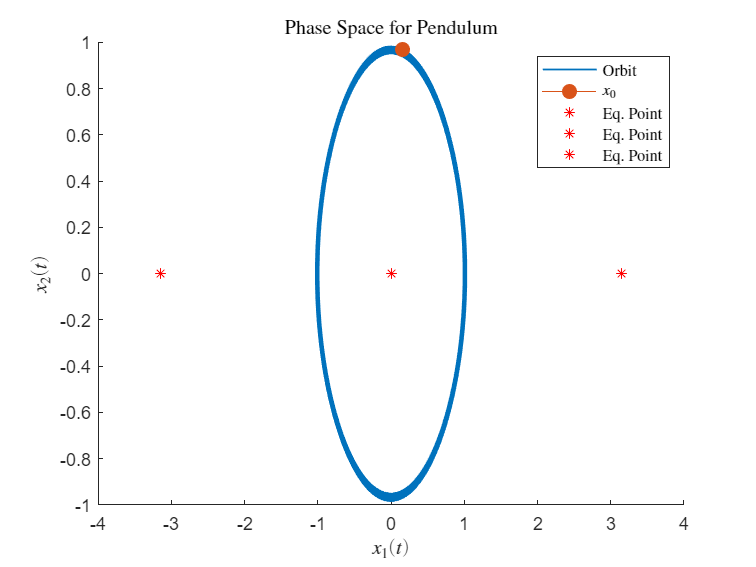

% x'' + sin(x) = 0

pendulum_nofric = @(t, x) [
    x(2);
    - sin(x(1))];

x0 = rand(2, 1);
[t, x] = ode45(pendulum_nofric, time_span, x0);
figure;

% Equilibrium Points
x_eq1 = [0, 0];
x_eq2 = [-pi, 0];
x_eq3 = [pi, 0];

figure;
ax6 = gca;
hold(ax6, 'all');
title(ax6, 'Phase Space for Pendulum', 'Interpreter', 'latex');
plot(ax6, x(:, 1), x(:, 2), 'LineWidth', 1, DisplayName='Orbit');
plot(ax6, x0(1), x0(2), 'Marker', '.', 'MarkerSize', 25, DisplayName='$x_0$');
plot(ax6, x_eq1(1), x_eq1(2), '*r', x_eq2(1), x_eq2(2), '*r', x_eq3(1), x_eq3(2), '*r', DisplayName='Eq. Point');
xlabel('$x_1(t)$', 'Interpreter', 'latex');
ylabel('$x_2(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');

## Chaotic Behavior of the Pendulum 

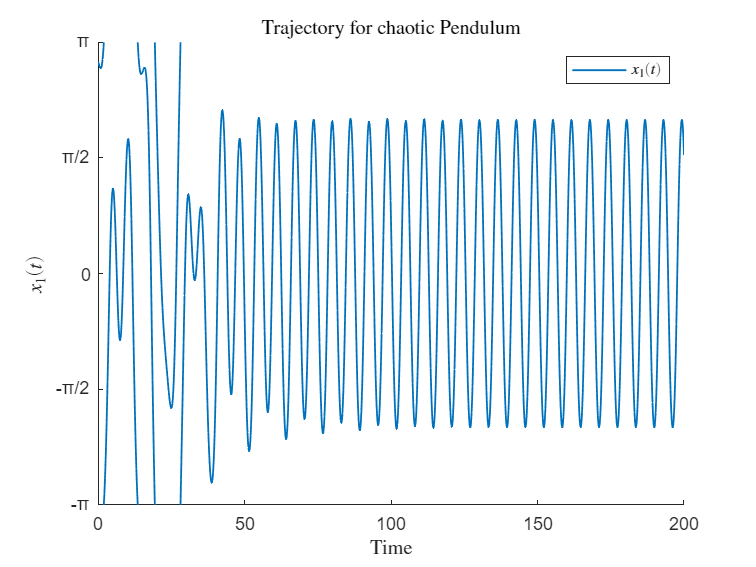

% x'' + sin x + cx = sin(t)


c = 0.01;
pend_chaotic = @(t, x) [
    x(2);
    - sin(x(1)) - c*x(2) + sin(t)];

x0 = 2*rand(2, 1) * 2 * pi - pi;
[t, x] = ode45(pend_chaotic, time_span, x0);

wrapped_angle = mod(x(:, 1) + pi, 2*pi) - pi;

% Detect discontinuities in the wrapped angle (where jumps larger than pi occur)
discontinuity_indices = find(abs(diff(wrapped_angle)) > pi);

% Insert NaNs at discontinuity indices
wrapped_angle_with_nan = wrapped_angle;
wrapped_angle_with_nan(discontinuity_indices + 1) = NaN;

% Now plotting the corrected wrapped angle with NaNs
figure;
ax11 = gca;
hold(ax11, 'all');
title(ax11, 'Trajectory for chaotic Pendulum', 'Interpreter', 'latex');
plot(ax11, t, wrapped_angle_with_nan, 'LineWidth', 1, 'DisplayName', '$x_1(t)$');  % Unwrap angle for x1
xlabel('Time', 'Interpreter', 'latex');
ylabel('$x_1(t)$', 'Interpreter', 'latex');
ylim([-pi pi]);
yticks([-pi -pi/2 0 pi/2 pi]);
yticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
legend('Interpreter', 'latex');

**Exercise: Try to plot the Phase Space for different initial conditions resembling the picture in the Slides**

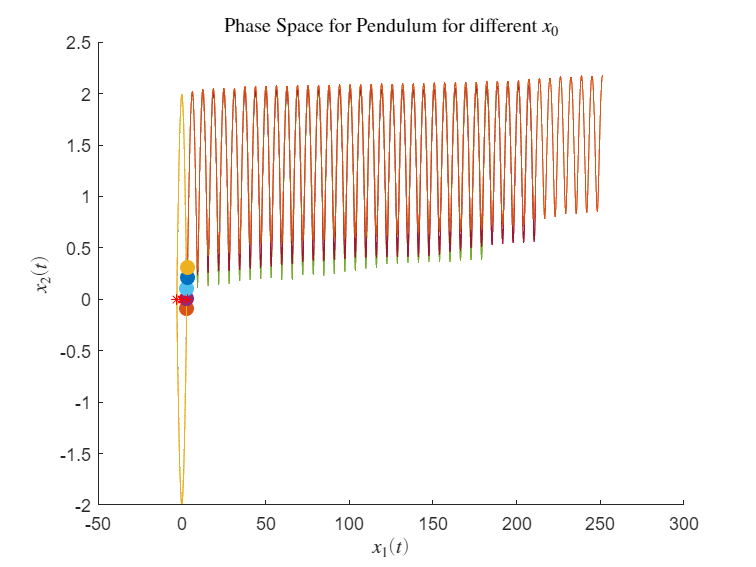

% Try to plot the Phase Space for different initial conditions resembling
% the picture in the Slides

n_trials = 5;
delta = 0.1;

figure;
ax7 = gca;
hold(ax7, 'all');
title(ax7, 'Phase Space for Pendulum for different $x_0$', 'Interpreter', 'latex');
for i=1:n_trials
    [t, x] = ode45(pendulum_nofric, time_span, x0);
    plot(ax7, x(:, 1), x(:, 2));
    plot(ax7, x0(1), x0(2), 'Marker','.', 'MarkerSize', 25)
    x0 = x0 + delta;
end
plot(ax7, x_eq1(1), x_eq1(2), '*r', x_eq2(1), x_eq2(2), '*r', x_eq3(1), x_eq3(2), '*r', DisplayName='Eq. Point');
xlabel(ax7, '$x_1(t)$', 'Interpreter','latex');
ylabel(ax7, '$x_2(t)$', 'Interpreter','latex');

## Extra Material - Discretized Pendulum

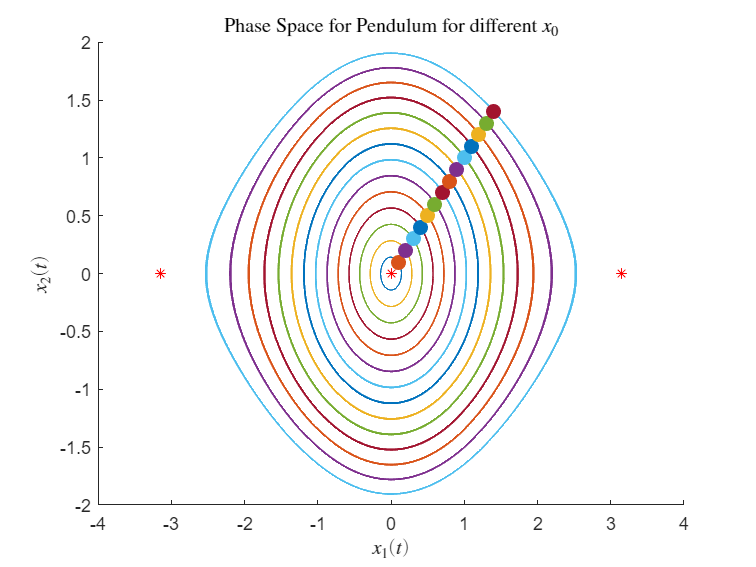

params = get_pendulum_params(1, 1, 0);
n_steps = T/dt;
xx = zeros(n_steps, 2);
x0 = [0.1; 0.1];

n_trials = 14;
delta = 0.1;
figure;
ax8 = gca;
hold(ax8, 'all');
title(ax8, 'Phase Space for Pendulum for different $x_0$', 'Interpreter', 'latex');
for i=1:n_trials
%     fprintf('Trial number %d\n', i)
    xx = zeros(n_steps, 2);
    xx(1, :) = x0;
    for k=1:n_steps
    xx(k + 1, :) = discretized_pend(xx(k, :), params, dt);
    end
    plot(ax8, xx(:, 1), xx(:, 2));
    plot(ax8, x0(1), x0(2), 'Marker','.', 'MarkerSize', 25)
    x0 = x0 + delta;
end
plot(ax8, x_eq1(1), x_eq1(2), '*r', x_eq2(1), x_eq2(2), '*r', x_eq3(1), x_eq3(2), '*r', DisplayName='Eq. Point');
xlabel(ax8, '$x_1(t)$', 'Interpreter','latex');
ylabel(ax8, '$x_2(t)$', 'Interpreter','latex');

## FitzHughNagumo - Excitable Behavior of neurons

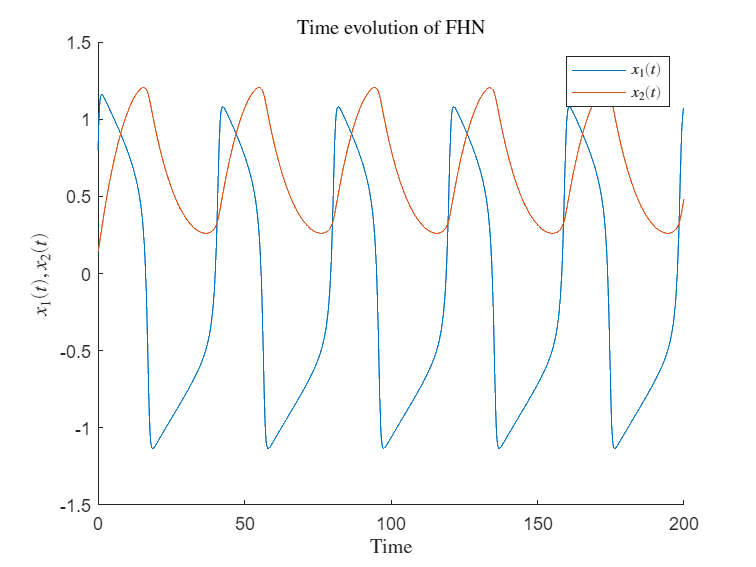

% FHN parameters
a = 0.7;
b = 0.8;
tau = 13;
x0 = rand(1, 2);
%I = 0.5; 
I = 0.7; 

fhn = @(t, x) [
    x(1) - x(1)^3 - x(2) + I;
    (1/tau)*(x(1) - b*x(2) + a)];

[t, x] = ode45(fhn, time_span, x0);


figure;
ax9 = gca;
hold(ax9, 'all');
title(ax9, 'Time evolution of FHN', 'Interpreter', 'latex');
plot(ax9, t, x(:, 1), DisplayName='$x_1(t)$');
plot(ax9, t, x(:, 2), DisplayName='$x_2(t)$');
xlabel('Time', 'Interpreter','latex')
ylabel('$x_1(t), x_2(t)$', 'Interpreter','latex')
legend('Interpreter', 'latex');

## Vector Filed of FHN - Nullclines

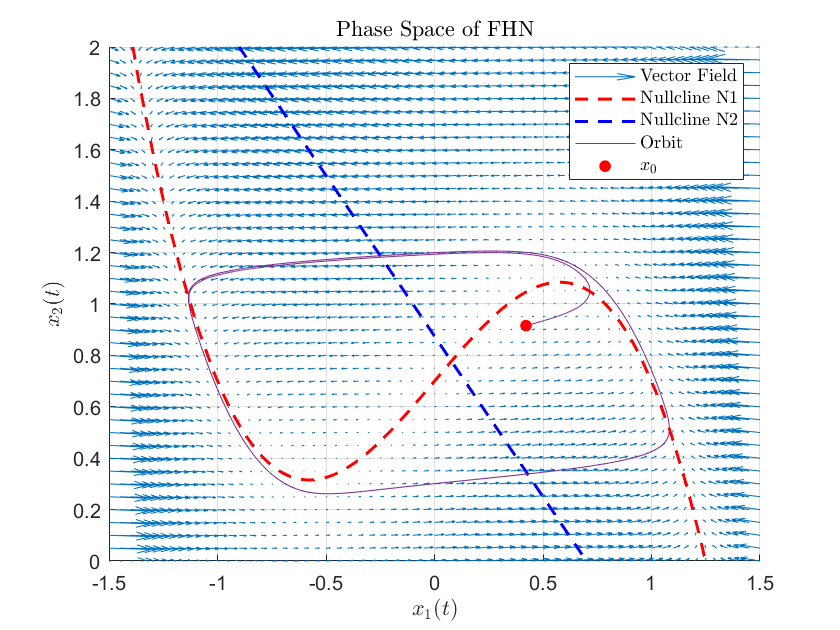

% FHN parameters
a = 0.7;
b = 0.8;
tau = 13;
I = 0.7; 

x0 = rand(1, 2);

nullcline1 = @(x1) x1 - x1.^3 + I; % N1
nullcline2 = @(x2) (a - x2) / b;    % N2

[x1_max, x1_min] = deal(1.5, -1.5);
[x2_max, x2_min] = deal(2, 0);
dens = 0.05;

[x1, x2] = meshgrid(x1_min:dens:x1_max, x2_min:dens:x2_max);
u = x1 - x1.^3 - x2 + I;   % dx/dt
v = (1/tau) * (x1 - b*x2 + a);  % dy/dt

[t, x] = ode45(fhn, time_span, x0);

figure;
ax10 = gca;
hold(ax10, 'all');
title(ax10, 'Phase Space of FHN', 'Interpreter', 'latex');

% Plot the vector field
quiver(ax10, x1, x2, u, v, 3.5, 'AutoScale', 'off', 'AutoScaleFactor', 0.5, 'DisplayName', 'Vector Field');
hold(ax10, 'on');

% Plot nullclines
fplot(ax10, nullcline1, [-2, 2], 'r--', 'LineWidth', 1.5, DisplayName='Nullcline N1'); % Nullcline N1
fplot(ax10, nullcline2, [-2, 2], 'b--', 'LineWidth', 1.5, DisplayName='Nullcline N2'); % Nullcline N2

plot(ax10, x(:, 1), x(:, 2), '-', DisplayName='Orbit');
plot(ax10, x0(1), x0(2), '.r', 'MarkerSize', 20, DisplayName='$x_0$');

xlabel('$x_1(t)$', 'Interpreter', 'latex');
ylabel('$x_2(t)$', 'Interpreter', 'latex');
xlim([x1_min, x1_max]);
ylim([x2_min, x2_max]);
legend('Interpreter', 'latex');
grid on;
hold off;

function x_plus = discretized_pend(xx, params, dt)
    nx = length(xx);
    x_plus = zeros(nx, 1);
    g = params.g;
    l = params.l;
    c = params.c;

    x_plus(1) = xx(1) + dt*xx(2);
    x_plus(2) = xx(2) + dt*(- (g/l) * sin(xx(1)) - c*l * xx(2));
end

function params = get_pendulum_params(g, l, c)
    params.g = g;
    params.l = l;
    params.c = c;
end
